# Homework 1: Basic Image Manipulation

#### Name: Grant Roberts

#### Date: 01/22/2020

#### Due: 02/04/2020

#### BMI/CS 567: Medical Image Analysis 

**In this homework you will practice some basic image manipulations such as color model transformations, color channel separation, and scaling.**

- **(a) Load the brain.png image into Matlab. You can download it from **`https://danielpimentel.github.io/teaching/BMI567.html`**. Display its size. Use Matlab's subplot function to display the image along with its RGB channels**

% cd('E:\Classwork\Spring 2020 Classwork\BMI567\Homework1'); % desktop
% cd('C:\Documents\Graduate Schoolwork\BMI567\Homework1'); % laptop
brain = imread('brain.jpg');
size(brain)

ans =    360   480     3


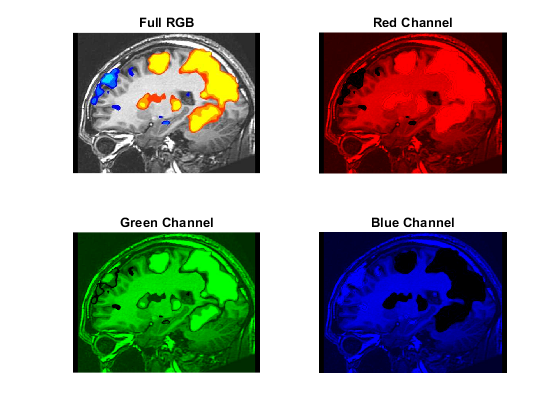


red = zeros(size(brain),'uint8');
green = red;
blue = red;
red(:,:,1) = brain(:,:,1);
green(:,:,2) = brain(:,:,2);
blue(:,:,3) = brain(:,:,3);

figure; subplot(2,2,1); imshow(brain); title('Full RGB');
subplot(2,2,2); imshow(red); title('Red Channel');
subplot(2,2,3); imshow(green); title('Green Channel');
subplot(2,2,4); imshow(blue); title('Blue Channel');

- **(b) Transform the image from RGB color values (default) into NTSC color space. How many components does the NTSC image have (in other words, what is its size)? Use subplot to display its components.**

brainNTSC = rgb2yiq(brain);
size(brainNTSC)

ans =    360   480     3


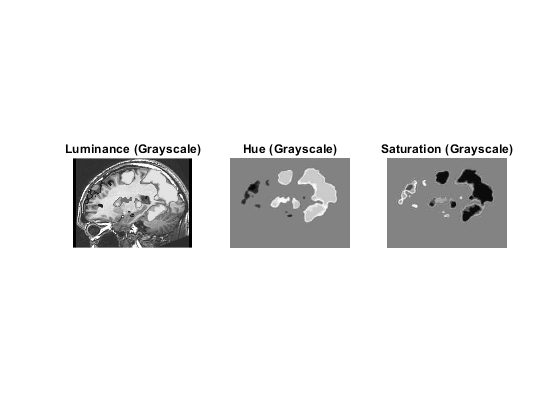

% Displaying in grayscale
figure; subplot(1,3,1); imshow(brainNTSC(:,:,1),[]); title('Luminance (Grayscale)');
subplot(1,3,2); imshow(brainNTSC(:,:,2),[]); title('Hue (Grayscale)');
subplot(1,3,3); imshow(brainNTSC(:,:,3),[]); title('Saturation (Grayscale)');

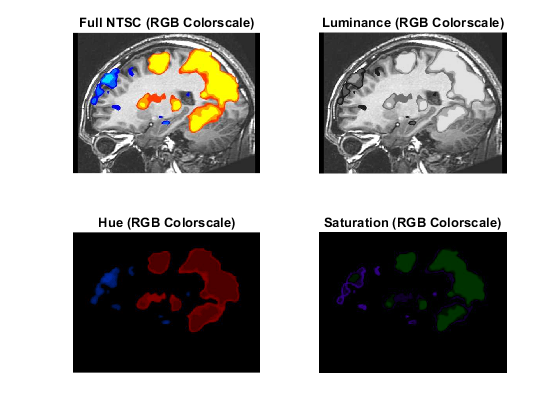


% Going back to RGB colorspace
luminance = zeros(size(brain),'double');
hue = luminance;
saturation = hue;
luminance(:,:,1) = brainNTSC(:,:,1);
hue(:,:,2) = brainNTSC(:,:,2);
saturation(:,:,3) = brainNTSC(:,:,3);
NTSC = yiq2rgb(brainNTSC);

Y = yiq2rgb(luminance);
I = yiq2rgb(hue);
Q = yiq2rgb(saturation);

figure; subplot(2,2,1); imshow(NTSC); title('Full NTSC (RGB Colorscale)');
subplot(2,2,2); imshow(Y); title('Luminance (RGB Colorscale)');
subplot(2,2,3); imshow(I); title('Hue (RGB Colorscale)');
subplot(2,2,4); imshow(Q); title('Saturation (RGB Colorscale)');

- **(c) Write your own function to transform an RGB image into grayscale (you cannot use any built in or downloaded Matlab function). Apply your function to our brain image. Use subplot to display it alongside the result of Matlab's built in function **`rgb2gray`** and alongside the Y component in NTSC color space. Are they similar at all?**

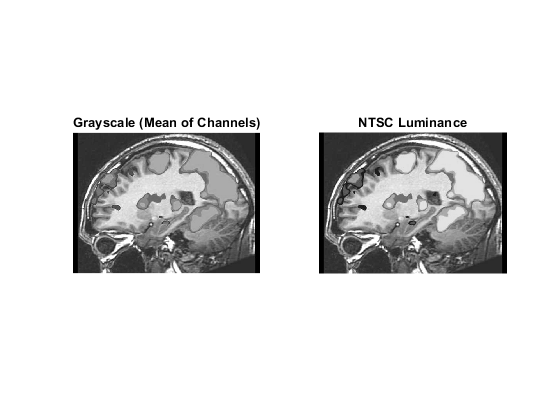

% FUNCTION AT BOTTOM OF SCRIPT
brainGray = rgb2grayscale(brain);
figure; subplot(1,2,1); imshow(brainGray,[]); title('Grayscale (Mean of Channels)');
subplot(1,2,2); imshow(Y,[]); title('NTSC Luminance');

The images are very similar, particularly in regards to the background 'gray' image of the brain. The colored ROI regions, however, differ between the two images. This is intuitive since the grayscale image is an average of the 3 RGB components, i.e. (0.333*R + 0.333*G + 0.333*B), which is very similar to the luminance (Y) component of YIQ (0.3*R + 0.59*G + 0.11*B) just with different weights on the RGB components.

- **(d) Write your own function to scale an image (you cannot use any built in or downloaded Matlab function). Apply your function to scale our brain image by 1/2 and by 2. Display your results.**

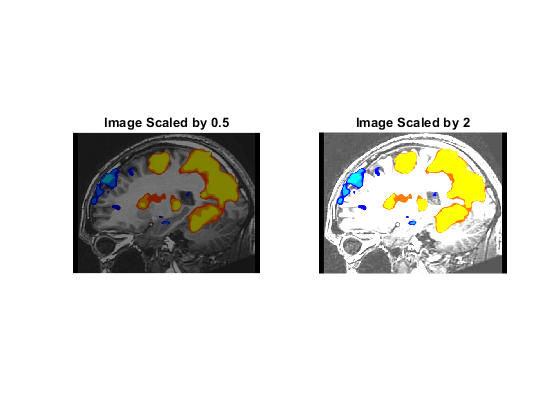

scaledImageHalf = imscale(brain,0.5);
scaledImage2 = imscale(brain,2);
figure; subplot(1,2,1); imshow(scaledImageHalf); title('Image Scaled by 0.5');
subplot(1,2,2); imshow(scaledImage2); title('Image Scaled by 2');

### Custom Functions

function yiq = rgb2yiq(rgb)
    %F = [0.300 0.5900 0.1100; 0.599 -0.2773 -0.3217;0.213 -0.5251 0.3121]; %forward to yiq
    rgb = double(rgb);
    yiq(:,:,1) = 0.300.*rgb(:,:,1) + 0.5900.*rgb(:,:,2) + 0.1100.*rgb(:,:,3);
    yiq(:,:,2) = 0.599.*rgb(:,:,1) - 0.2773.*rgb(:,:,2) - 0.3217.*rgb(:,:,3);
    yiq(:,:,3) = 0.213.*rgb(:,:,1) - 0.5251.*rgb(:,:,2) + 0.3121.*rgb(:,:,3);
end 

function rgb = yiq2rgb(yiq)
    %R = pinv(F); %reverse back to rgb
    rgb(:,:,1) = yiq(:,:,1) + 0.9469.*yiq(:,:,2) + 0.6236.*yiq(:,:,3);
    rgb(:,:,2) = yiq(:,:,1) - 0.2748.*yiq(:,:,2) - 0.6357.*yiq(:,:,3);
    rgb(:,:,3) = yiq(:,:,1) - 1.1085.*yiq(:,:,2) + 1.7090.*yiq(:,:,3);
    rgb = uint8(rgb);
end

function grayscale = rgb2grayscale(rgb)
    grayscale = mean(rgb,3);
end

function scaledImage = imscale(image,scaleFactor)
    scaledImage = image.*scaleFactor; 
end

### References

[http://matlab.izmiran.ru/help/toolbox/images/color10.html](http://matlab.izmiran.ru/help/toolbox/images/color10.html)

[https://www.eembc.org/techlit/datasheets/yiq_consumer.pdf](https://www.eembc.org/techlit/datasheets/yiq_consumer.pdf)